# **Controllo di un sistema massa-molla**

Si consideri un sistema composto da due masse e tre molle.

- Il primo blocco ha massa $m_1$ ed è spinto da una forza $u_1$

- Il secondo blocco ha massa $m_2$ ed è spinto da una forza $u_2$

- La prima e la terza molla hanno coefficiente elastico $k_1$

- La seconda molla ha coefficiente elastico $k_2$

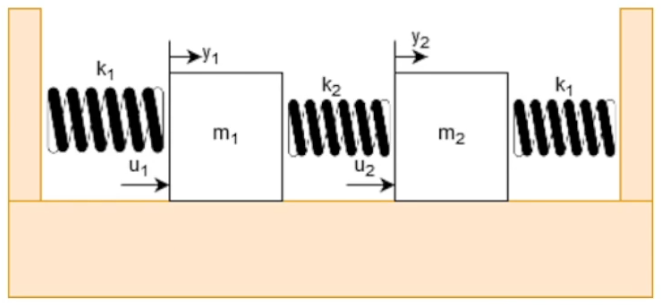

## Modellazione del sistema

Il sistema massa-molla in questione può essere visto come un sistema MIMO a due ingressi (le forze applicate ai due blocchi) e due uscite (lo spostamento dei due blocchi).

### Formulazione matematica

Dalla legge di Hooke, per la prima massa:


$$u_1 \left(t\right)-k_1 y_1 \left(t\right)-k_2 \left(y_1 \left(t\right)-y_2 \left(t\right)\right)=m_1 \ddot{y_1 } \left(t\right)$$



$$\ddot{y_1 } \left(t\right)=\frac{1}{m_1 }u_1 \left(t\right)-\frac{k_1 +k_2 }{m_1 }y_1 \left(t\right)+\frac{k_2 }{m_1 }y_2 \left(t\right)$$


Dalla legge di Hooke, per la seconda massa:


$$u_2 \left(t\right)-k_2 y_2 \left(t\right)-\left(k_1 +k_2 \right)y_2 \left(t\right)=m_2 \ddot{y_2 } \left(t\right)$$



$$\ddot{y_2 } \left(t\right)=\frac{1}{m_2 }u_2 \left(t\right)+\frac{k_2 }{m_2 }y_1 \left(t\right)-\frac{k_1 +k_2 }{m_2 }y_2 \left(t\right)$$


### Rappresentazione nello spazio di stato

Considerando le seguenti variabili di stato:

- $x_1 \left(t\right)=y_1 \left(t\right)$ la posizione del primo blocco

- $x_2 \left(t\right)=\dot{y_1 } \left(t\right)$ la velocità del primo blocco

- $x_3 \left(t\right)=y_2 \left(t\right)$ la posizione del secondo blocco

- $x_4 \left(t\right)=\dot{y_2 } \left(t\right)$ la velocità del secondo blocco

il sistema può essere espresso nella forma:


$$\left\lbrack \begin{array}{c}
\dot{x_1 } \left(t\right)\\
\dot{x_2 } \left(t\right)\\
\dot{x_3 } \left(t\right)\\
\dot{x_4 } \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
-\frac{k_1 +k_2 }{m_1 } & 0 & \frac{k_2 }{m_1 } & 0\\
0 & 0 & 0 & 1\\
\frac{k_2 }{m_2 } & 0 & -\frac{k_1 +k_2 }{m_2 } & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \left(t\right)\\
x_2 \left(t\right)\\
x_3 \left(t\right)\\
x_4 \left(t\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
\frac{1}{m_1 } & 0\\
0 & 0\\
0 & \frac{1}{m_2 }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_1 \left(t\right)\\
u_2 \left(t\right)
\end{array}\right\rbrack$$


$\left\lbrack \begin{array}{c}
y_1 \left(t\right)\\
y_2 \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 0 & 1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \left(t\right)\\
x_2 \left(t\right)\\
x_3 \left(t\right)\\
x_4 \left(t\right)
\end{array}\right\rbrack$+$\left\lbrack \begin{array}{cc}
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_1 \left(t\right)\\
u_2 \left(t\right)
\end{array}\right\rbrack$

## Implementazione del sistema

% Operazioni preliminari
close all;
clear all; 
clc;

### Parametri del sistema

% Coefficienti elastici [N/m]
k1 = 1;
k2 = 2;

% Masse dei blocchi [kg]
m1 = 1;
m2 = 1.5;

### Matrici del sistema

% Matrici del sistema
A = [0,           1, 0,           0;
     -(k1+k2)/m1, 0, k2/m1,       0;
     0,           0, 0,           1;
     k2/m2,       0, -(k1+k2)/m2, 0];

B = [0,    0;
     1/m1, 0;
     0,    0;
     0,    1/m2];

C = [1, 0, 0, 0;
     0, 0, 1, 0];

D = [0, 0;
     0, 0];

### Definizione del sistema

% Sistema nello spazio di stato
plant = ss(A,B,C,D);

### Analisi del sistema

% Risposta in anello aperto
% impulse(plant);
% step(plant);

Si tratta di un comportamento prevedibile, considerando che gli autovalori della matrice di stato sono due coppie di autovalori complessi e coniugati.

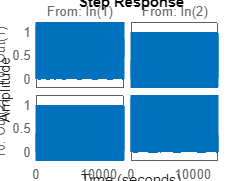

% Autovalori del sistema

eigenvalues = eig(A)

## Controllo del sistema

Una volta implementato il sistema da controllare, è necessario definire il controllore MPC ed i corrispettivi parametri.

### Parametri del controllo

% Periodo di campionamento
Ts = 0.1;   % 10 Hz

eigenvalues =    0.0000 + 2.0513i
   0.0000 - 2.0513i
  -0.0000 + 0.8900i
  -0.0000 - 0.8900i



% Orizzonte di predizione
Hp = 10;

% Orizzonte di controllo
Hc = 2;

### Definizione del controllore

% Controllore MPC
mpcobj = mpc(plant,Ts,Hp,Hc);

### Simulazione del controllo

Si supponga di voler controllare il sistema in modo che il primo blocco di massa $m_1$ si muova di un metro e che il secondo blocco di massa $m_2$ resti fermo nella sua posizione iniziale.

% Riferimento
yref = [1, 0];

È necessario eseguire una simulazione in anello chiuso, la cui durata dipende dal numero di step desiderati alla frequenza già imposta con il periodo di campionamento. Ad esempio, avendo imposto una frequenza di campionamento di 10 Hz, per eseguire una simulazione di 3 secondi è necessario specificare 30 step.

-->"Weights.ManipulatedVariables" is empty. Assuming default 0.00000.
-->"Weights.ManipulatedVariablesRate" is empty. Assuming default 0.10000.
-->"Weights.OutputVariables" is empty. Assuming default 1.00000.


-->Converting model to discrete time.
-->Assuming output disturbance added to measured output #1 is integrated white noise.
-->Assuming output disturbance added to measured output #2 is integrated white noise.
-->"Model.Noise" is empty. Assuming white noise on each measured output.


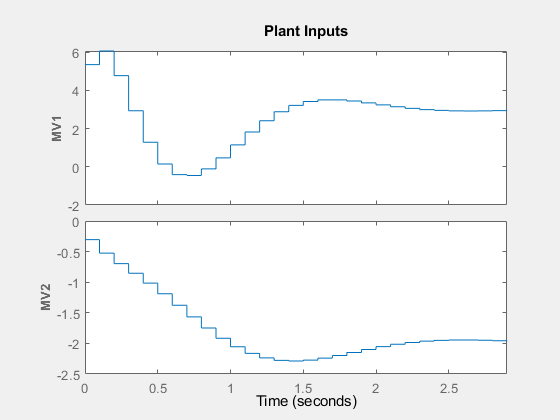

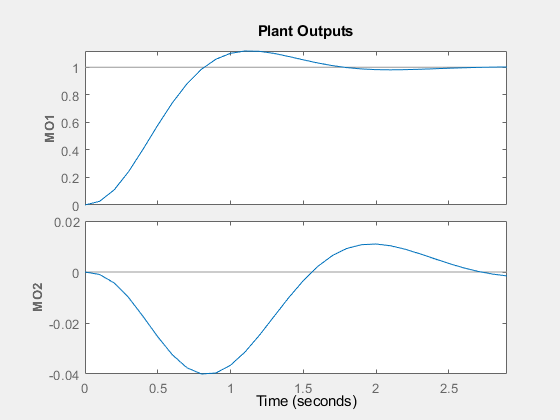

% Simulazione del controllo
sim(mpcobj, 30, yref);

### Analisi dei risultati

La simulazione restituisce due coppie di grafici, che illustrano rispettivamente l'evoluzione degli ingressi e delle uscite del sistema.

Per quel che concerne gli ingressi, è possibile osservare come:

- La forza applicata al primo blocco di massa $m_1$ cresce inizialmente fino a 6 N, poi decresce portandosi a valori negativi, ed infine si stabilizza ad un valore di circa 3 N.

- La forza applicata al secondo blocco di massa $m_2$ decresce fino a stabilizzarsi ad un valore di circa - 2 N. Il fatto che la forza applicata sia negativa è indice del fatto che si stia opponendo allo spostamento del primo blocco.

Per quel che concerne le uscite, è possibile osservare come:

- Lo spostamento del primo blocco si stabilizza a 1 m.

- Lo spostamento del secondo blocco si stabilizza a 0 m a seguito di un certo comportamento oscillatorio dovuto alla compensazione dello spostamento del primo blocco.

Sebbene l'andamento della seconda uscita possa non sembrare molto incoraggiante, è bene osservare la scala utilizzata dal plot. Il controllore si dimostra quindi efficace, perché i picchi delle oscillazioni più importanti hanno ampiezza, rispettivamente, di -4 cm e di 1 cm. Si tratta di variazioni di due ordini di grandezza inferiori rispetto al riferimento desiderato.

Infine, è importante osservare come il sistema riesca a stabilizzarsi dopo poco più di 2 secondi dall'inizio della simulazione, con un massimo overshoot di circa 12 cm.